# COMPONENTS & PROPERTIES INPUTS PAGE

Use this page to load/edit the half car component inputs like springs,tires etc

** NOTE 

This script is divided into many different sections. The grouping is done based on some similarities. 

To run the sections individually (which will save time) click anywhere on the section and then click the 

`Run Section` button.

A section is demarcated by a blue border.

## `LEGEND`

% Comments (in green) can indicate notes or units 
"EDIT FIELD"; % Indicates a user input is expected

`--- INTERNAL ---` = Code below this heading is for internal use only 

`--- USER ---` = Code below this is is for the user to edit. It can also contain plotting commands for data visualization

## HALF CAR PROPERTIES

This section contains half car parameters like wheelbase, mass etc.,

**Instructions :-**

- *Use textbox to edit value *

- *Comment on right contains property name and unit*

### `--- USER ---` Properties

%%%%%%%%%%%%%%%%%%%%%%% Safety %%%%%%%%%%%%%%%%%%%%%%%%%%%%
A = exist('hcar','var');

if A == 0
    hcar = HCar;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Half Car Properties

hcar.mass_sm = 400; % [Kg] | Suspended Mass
hcar.mass_sm_dis = 50; % [%] | Suspended Mass Distribution
hcar.Inertia = 600; % [Kgm^2] | Suspended Mass Inertia
hcar.Inertia_NSM_1 = 2.4; % [Kgm^2] | Unsprung Mass Inertia - Front
hcar.Inertia_NSM_2 = 3.2; % [Kgm^2] | Unsprung Mass Inertia - Rear
hcar.mass_usm_1 = 42; % [Kg] | Unsprung Mass - Front
hcar.mass_usm_2 = 42; % [Kg] | Unsprung Mass - Rear
hcar.w2w = 3; % [m] - Wheelbase
hcar.cg_SM_Height = 0.336; % [m] | CG Height - Suspended Mass
hcar.cg_USM_Height = 0.225; % [m] | CG Height - Unsprung Mass Front
hcar.cg_USM_Height2 = 0.225; % [m] | CG HEight - Unsprung Mass Rear
hcar.rh_1 = 0.067; % [m] | Ride Height - Front
hcar.rh_2 = 0.081; % [m] | Ride Height - Rear
hcar.a_RH_X = 0.25; % [m] | RH Measurement Point X Coordinate - Front
hcar.b_RH_X = -3.25; % [m] | RH Measurement Point X Coordinate - Rear

## COMPONENT PROPERTIES

Here all the individual components (springs,dampers etc.,) of the half car are considered

### --- INTERNAL --- INITIALIZATION

% Spring Initialization
fSpring = Spring();
rSpring = Spring();

% Bumpstop Initialization
fBS = Bumpstop;
rBS = Bumpstop;

% Coilover Initialization
fCoil = Coilover;
rCoil = Coilover;

% Damper Initialization
fDamper = Damper;
rDamper = Damper;

% Tire Initialization
fTire = TireCus;
rTire = TireCus;

% Suspension Initialization
susp = AxleSuspension;

% Aerodynamics Initialization
aero = Aerodynamics;

### `--- USER ---` Springs

#### ***Important Instructions***

- For Force vs Deflection data template please refer to the excel sheet in folder Component Files-> Springs

- Units of Deflection --> **[m]**

- Units of Force --> **[N]**

- Please ensure that the first row of the excel sheet being important consists of only column names without any special characters. If there are any special characters (including space, you will get a warning. The software will NOT fail but you will get a warning.

- Please ensure that the excel sheet is not open during importing. An error message will be displayed if the excel sheet is open in Microsoft Excel while the code to import the file is being run. 

- *Graphs plotted in [N] vs [mm] **only for convenience**. Units are still [m]*

% --- FRONT SPRINGS --- 
disp(" -------- FRONT SPRINGS -------- ");

 -------- FRONT SPRINGS -------- 


fSpring.freeLength = 0.2; % [m] | Free Length of Spring - Front
fSpring.stroke = 0.1; % [m] | Stroke of Spring - Front
    forceDefData  = readtable("LMP_Spring.xlsx") % Importing Force vs Deflection data

forceDefData = 6×2 table
    Deflection_m    Force_N
    ____________    _______

           0             0 
        0.02          6780 
        0.04         13560 
        0.06         20340 
        0.08         27120 
         0.1         33900 


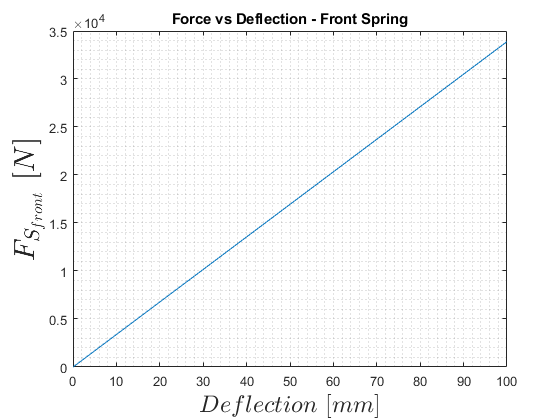

fSpring.forceDefData = [forceDefData.Variables];

plot(fSpring.forceDefData(:,1)*1000,fSpring.forceDefData(:,2));
title("Force vs Deflection - Front Spring");
ylabel({'$F_{S_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$Deflection\ [mm]$'},'Interpreter','latex','FontSize',18);
grid minor;



% --- REAR SPRINGS --- 
disp(" -------- REAR SPRINGS -------- ");

 -------- REAR SPRINGS -------- 


rSpring.freeLength = 0.2; % [m] | Free Length of Spring - Front
rSpring.stroke = 0.1; % [m] | Stroke of Spring - Front
    forceDefData  = readtable("LMP_Spring.xlsx") % Importing Force vs Deflection data

forceDefData = 6×2 table
    Deflection_m    Force_N
    ____________    _______

           0             0 
        0.02          6780 
        0.04         13560 
        0.06         20340 
        0.08         27120 
         0.1         33900 


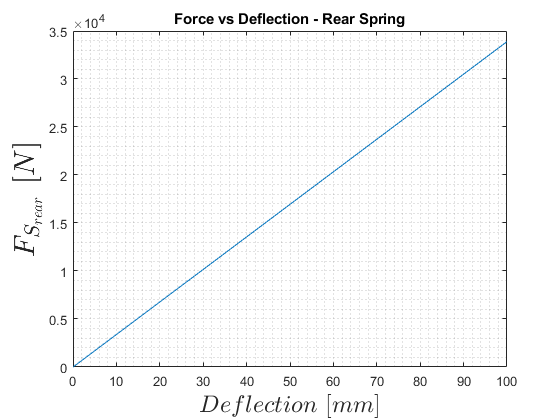

rSpring.forceDefData = [forceDefData.Variables];

plot(rSpring.forceDefData(:,1)*1000,rSpring.forceDefData(:,2));
title("Force vs Deflection - Rear Spring");
ylabel({'$F_{S_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$Deflection\ [mm]$'},'Interpreter','latex','FontSize',18);
grid minor;

### `--- USER ---` Bumpstops

#### ***Important Instructions***

- For Force vs Deflection data template please refer to the excel sheet in folder Component Files-> Bumpstops

- Units of Deflection --> **[m]**

- Units of Force --> **[N]**

- Please ensure that the first row of the excel sheet being important consists of only column names without any special characters. If there are any special characters (including space, you will get a warning. The software will NOT fail but you will get a warning.

- Please ensure that the excel sheet is not open during importing. An error message will be displayed if the excel sheet is open in Microsoft Excel while the code to import the file is being run. 

- *Graphs plotted in [N] vs [mm] **only for convenience**. Units are still [m]*

% --- FRONT BUMPSTOPS --- 
disp(" -------- FRONT BUMPSTOPS -------- ");

 -------- FRONT BUMPSTOPS -------- 


fBS.freeLength = 0.015; % [m] | Free Length of Bumpstop
fBS.stroke = 0.0145; % [m] | Stroke of Bumpstop
    forceDefData  = readtable("LMP_Bumpstop.xlsx") % Importing Force vs Deflection data

forceDefData = 29×2 table
    Deflection_m    Force_N
    ____________    _______

            0            0 
       0.0005         95.8 
        0.001        207.6 
       0.0015          324 
        0.002        437.7 
       0.0025        545.2 
        0.003        647.3 
       0.0035        748.4 
        0.004        857.2 
       0.0045        986.3 
        0.005       1152.4 
       0.0055       1375.9 
        0.006       1681.5 
       0.0065       2097.9 
        0.007       2657.4 
       0.0075       3396.9 


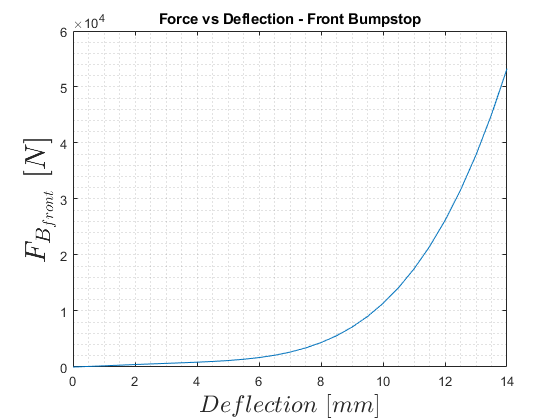

fBS.forceDefData = [forceDefData.Variables];

plot(fBS.forceDefData(:,1)*1000,fBS.forceDefData(:,2));
title("Force vs Deflection - Front Bumpstop");
ylabel({'$F_{B_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$Deflection\ [mm]$'},'Interpreter','latex','FontSize',18);
grid minor;


% --- REAR BUMPSTOPS --- 
disp(" -------- REAR BUMPSTOPS -------- ");

 -------- REAR BUMPSTOPS -------- 


rBS.freeLength = 0.015; % [m] | Free Length of Bumpstop
rBS.stroke = 0.0145; % [m] | Stroke of Bumpstop
    forceDefData  = readtable("LMP_Bumpstop.xlsx") % Importing Force vs Deflection data

forceDefData = 29×2 table
    Deflection_m    Force_N
    ____________    _______

            0            0 
       0.0005         95.8 
        0.001        207.6 
       0.0015          324 
        0.002        437.7 
       0.0025        545.2 
        0.003        647.3 
       0.0035        748.4 
        0.004        857.2 
       0.0045        986.3 
        0.005       1152.4 
       0.0055       1375.9 
        0.006       1681.5 
       0.0065       2097.9 
        0.007       2657.4 
       0.0075       3396.9 


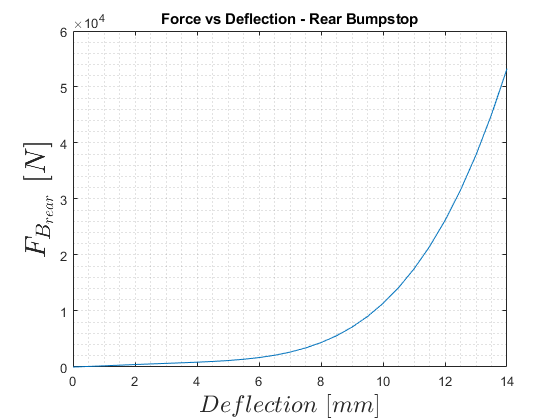

rBS.forceDefData = [forceDefData.Variables];

plot(rBS.forceDefData(:,1)*1000,rBS.forceDefData(:,2));
title("Force vs Deflection - Rear Bumpstop");
ylabel({'$F_{B_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$Deflection\ [mm]$'},'Interpreter','latex','FontSize',18);
grid minor;

### `--- USER ---` Coilovers

% --- FRONT COILOVERS --- 
disp(" -------- FRONT COILOVER -------- ");

 -------- FRONT COILOVER -------- 


fCoil.freeLength = 0.449; % [m] | Free Length of Coilover
fCoil.stroke = 0.048; % [m] | Stroke of Coilover
fCoil.bsGap = 0.038; % [m] | Bumpstop Gap
fCoil.springGap = 0.016; % [m] | Spring Gap

% --- REAR COILOVERS --- 
disp(" -------- REAR COILOVER -------- ");

 -------- REAR COILOVER -------- 


rCoil.freeLength = 0.449; % [m] | Free Length of Coilover
rCoil.stroke = 0.048; % [m] | Stroke of Coilover
rCoil.bsGap = 0.038; % [m] | Bumpstop Gap
rCoil.springGap = 0.016; % [m] | Spring Gap


%%%%%%%%%%%%%%%%%%%%%% --- INTERNAL --- Coilover Conditioning %%%%%%%%%%%%%
% Front Coilover Conditioning
fCoil.spring = fSpring;
fCoil.bumpStop = fBS;
fCoil = fCoil.Combine_ForceDefData();

% Rear Coilover Conditioning
rCoil.spring = fSpring;
rCoil.bumpStop = fBS;
rCoil = rCoil.Combine_ForceDefData();

### `--- USER ---` Dampers

#### ***Important Instructions***

- For Force vs Shaft Velocity data template please refer to the excel sheet in folder Component Files-> Dampers

- Units of Shaft Velocity --> **[m/s]**

- Units of Force --> **[N]**

- Please ensure that the first row of the excel sheet being important consists of only column names without any special characters. If there are any special characters (including space, you will get a warning. The software will NOT fail but you will get a warning.

- Please ensure that the excel sheet is not open during importing. An error message will be displayed if the excel sheet is open in Microsoft Excel while the code to import the file is being run. 

- *Graphs plotted in [N] vs [mm/s] **only for convenience**. Units are still [m/s]*

- *** NOTE : mps = meter/second!*

% --- FRONT DAMPERS ---
disp(" -------- FRONT DAMPER  -------- ");

 -------- FRONT DAMPER  -------- 


fDamper.freeLength = 0.35; % [m] | Free Length of Damper
fDamper.stroke = 0.15; % [m] | Stroke of Damper
fDamper.staticGasForce = 0; % [N] | Static Gas Pressure Force
    forceVelData = readtable("LMP_Damper.xlsx")

forceVelData = 11×2 table
    Shaft_Velocity_mps    Force_N
    __________________    _______

         -0.39061           -2409
         -0.07942         -879.13
          -0.0258         -287.18
         -0.01291         -123.84
         -0.00745         -77.754
                0               0
          0.00752          76.518
          0.01288          125.72
           0.0258          321.85
          0.07943          880.96
             0.39          1703.4


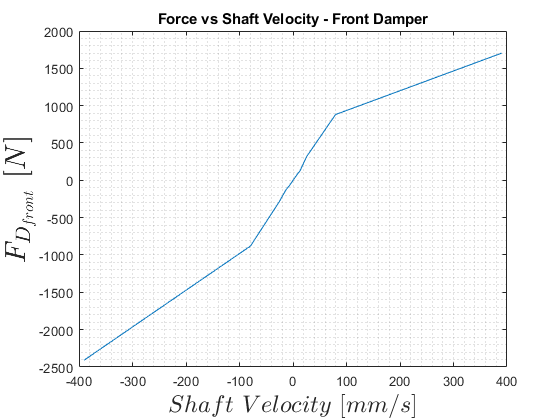

fDamper.forceVelData = forceVelData.Variables;

plot(fDamper.forceVelData(:,1)*1000,fDamper.forceVelData(:,2));
title("Force vs Shaft Velocity - Front Damper");
ylabel({'$F_{D_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$Shaft\ Velocity \ [mm/s]$'},'Interpreter','latex','FontSize',18);
grid minor;


% --- REAR DAMPERS ---
disp(" -------- REAR DAMPER -------- ");

 -------- REAR DAMPER -------- 


rDamper.freeLength = 0.35; % [m] | Free Length of Damper
rDamper.stroke = 0.15; % [m] | Stroke of Damper
rDamper.staticGasForce = 0; % [N] | Static Gas Pressure Force
    forceVelData = readtable("LMP_Damper.xlsx")

forceVelData = 11×2 table
    Shaft_Velocity_mps    Force_N
    __________________    _______

         -0.39061           -2409
         -0.07942         -879.13
          -0.0258         -287.18
         -0.01291         -123.84
         -0.00745         -77.754
                0               0
          0.00752          76.518
          0.01288          125.72
           0.0258          321.85
          0.07943          880.96
             0.39          1703.4


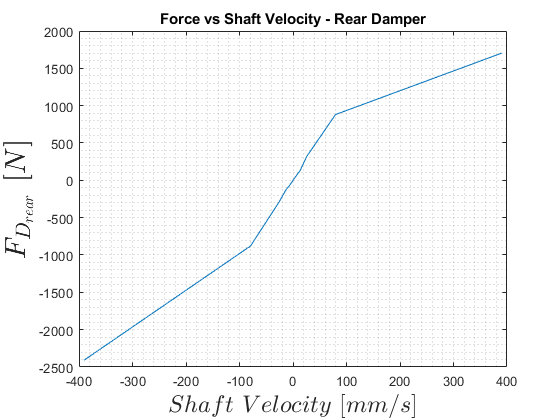

rDamper.forceVelData = forceVelData.Variables;

plot(rDamper.forceVelData(:,1)*1000,rDamper.forceVelData(:,2));
title("Force vs Shaft Velocity - Rear Damper");
ylabel({'$F_{D_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$Shaft\ Velocity \ [mm/s]$'},'Interpreter','latex','FontSize',18);
grid minor;

### `--- USER ---` Tires

% --- FRONT TIRES ---
disp(" -------- FRONT TIRE-------- ");

 -------- FRONT TIRE-------- 


fTire.kt = 200000; % [N/m] | Vertical Stiffness
fTire.dt = 8; % [Ns/m] | Vertical Damping Coefficient
fTire.unloadedRadius = 0.225; % [m] | Unloaded Radius
fTire.relX = 0.5; % [m] | Longitudinal Relaxation Length
fTire.mf = fTire.Init_MF_Coeff(); 
disp("To edit coefficients navigate to TireCus.m class");

To edit coefficients navigate to TireCus.m class


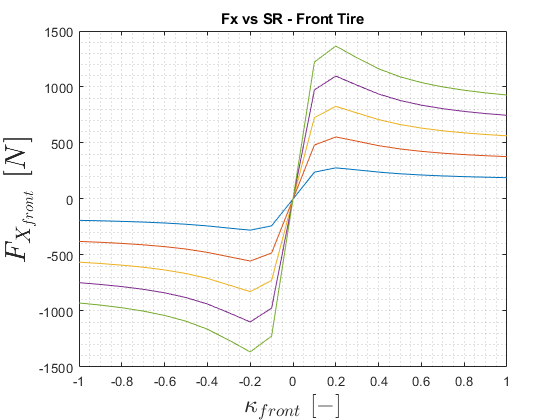


sr = -1:0.1:1;
fz = 200:200:1000;
figure();
for i = 1:length(fz)
    fx_f(i,:) = MF5ss_eval(fz(i),sr,0,0,fTire.mf);
    plot(sr,fx_f(i,:));
    hold on;
end
title("Fx vs SR - Front Tire");
ylabel({'$F_{X_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$\kappa_{front} \ [-]$'},'Interpreter','latex','FontSize',18);
grid minor;


% --- REAR TIRES ---
disp(" -------- REAR TIRE-------- ");

 -------- REAR TIRE-------- 


rTire.kt = 200000; % [N/m] | Vertical Stiffness
rTire.dt = 8; % [Ns/m] | Vertical Damping Coefficient
rTire.unloadedRadius = 0.225; % [m] | Unloaded Radius
rTire.relX = 0.5; % [m] | Longitudinal Relaxation Length
rTire.mf = rTire.Init_MF_Coeff();disp("To edit coefficients navigate to TireCus.m class");

To edit coefficients navigate to TireCus.m class


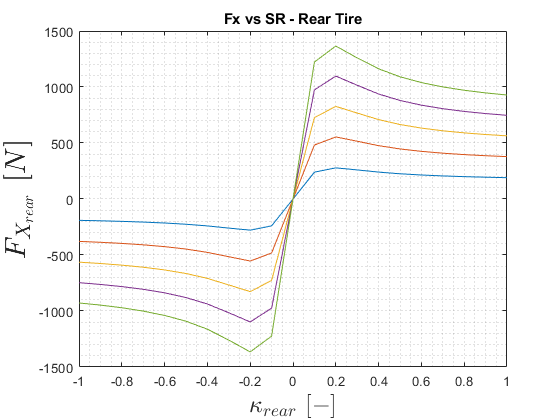


figure();
for i = 1:length(fz)
    fx_r(i,:) = MF5ss_eval(fz(i),sr,0,0,rTire.mf);
    plot(sr,fx_r(i,:));
    hold on;
end
title("Fx vs SR - Rear Tire");
ylabel({'$F_{X_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$\kappa_{rear} \ [-]$'},'Interpreter','latex','FontSize',18);
grid minor;

### `--- USER ---` Suspension

% --- FRONT SUSPENSION ---
disp(" -------- FRONT SUSPENSION -------- ");

 -------- FRONT SUSPENSION -------- 


susp.vsal_1 = 3.6; % [m] | Side View VSAL
susp.ich_1 = 0.35; % [m] | Side View IC Height

% --- REAR SUSPENSION ---
disp(" -------- REAR SUSPENSION -------- ");

 -------- REAR SUSPENSION -------- 


susp.vsal_2 = 3.6; % [m] | Side View VSAL
susp.ich_2 = 0.35; % [m] | Side View IC Height


### `--- USER ---` Aerodynamics

#### ***Important Instructions***

- For Aeromap template please refer to the excel sheet in folder Component Files-> Aerodynamics

- **IMPORTANT CHANGE**:- Units of Ride Heights --> **[mm]**

- Units of Coefficients --> **[-]**

- Units of Aerobalance --> **[%]**

- Please ensure that the first row of the excel sheet being important consists of only column names without any special characters. If there are any special characters (including space, you will get a warning. The software will NOT fail but you will get a warning.

- Please ensure that the excel sheet is not open during importing. An error message will be displayed if the excel sheet is open in Microsoft Excel while the code to import the file is being run. 

% --- VEHICLE AERODYNAMICS ---
aero.fArea = 1; % [m^2] | Frontal Area
aero.airDensity = 1.225; % [Kgm^3] | Air Density
    aeroMapImport = readtable('LMP_Aero.xlsx')

aeroMapImport = 2501×5 table
    Front_Ride_Height_mm    Rear_Ride_Height_mm    DownforceCoefficient    DragCoefficient    Aerobalance_Percent
    ____________________    ___________________    ____________________    _______________    ___________________

             30                     30                    5.843                 0.995               45.102       
             30                     31                    5.869                 0.996                45.11       
             30                     32                    5.893                 0.997                45.12       
             30                     33                    5.914                 0.997               45.131       
             30                     34                    5.932                 0.998               45.143       
  

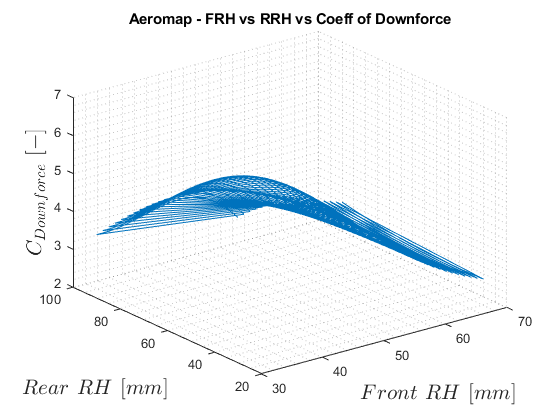

aero.aeromap = [aeroMapImport.Variables];

%%%%%%% INTERNAL %%%%%%%
aero.cDown = aero.aeromap(:,3);
aero.cDrag = aero.aeromap(:,4);
aero.cDist = aero.aeromap(:,5);

figure();
plot3(aero.aeromap(:,1),aero.aeromap(:,2),aero.cDown);
title("Aeromap - FRH vs RRH vs Coeff of Downforce");
zlabel({'$C_{Downforce}\ [-]$'},'Interpreter','latex','FontSize',16);
ylabel({'$Rear\ RH \ [mm]$'},'Interpreter','latex','FontSize',16);
xlabel({'$Front\ RH\ [mm]$'},'Interpreter','latex','FontSize',16);
grid minor;

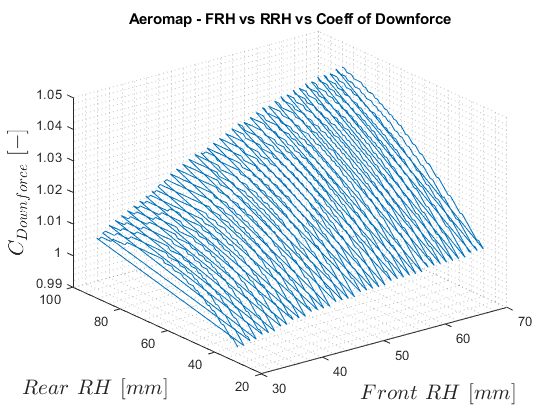


figure();
plot3(aero.aeromap(:,1),aero.aeromap(:,2),aero.cDrag);
title("Aeromap - FRH vs RRH vs Coeff of Downforce");
zlabel({'$C_{Downforce}\ [-]$'},'Interpreter','latex','FontSize',16);
ylabel({'$Rear\ RH \ [mm]$'},'Interpreter','latex','FontSize',16);
xlabel({'$Front\ RH\ [mm]$'},'Interpreter','latex','FontSize',16);
grid minor;

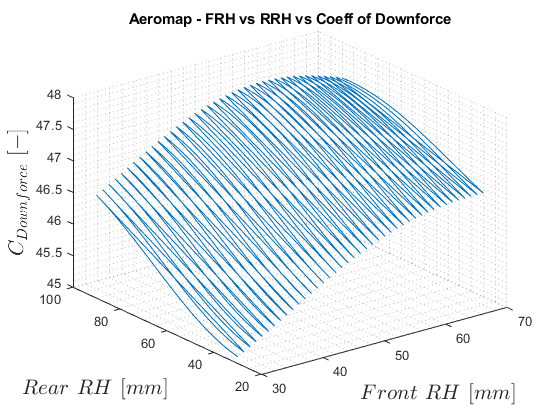


figure();
plot3(aero.aeromap(:,1),aero.aeromap(:,2),aero.cDist);
title("Aeromap - FRH vs RRH vs Coeff of Downforce");
zlabel({'$C_{Downforce}\ [-]$'},'Interpreter','latex','FontSize',16);
ylabel({'$Rear\ RH \ [mm]$'},'Interpreter','latex','FontSize',16);
xlabel({'$Front\ RH\ [mm]$'},'Interpreter','latex','FontSize',16);
grid minor;

%%%%%%%%%%%%%%%%%% --- INTERNAL --- HALFCAR CONDITIONING %%%%%%%%%%%%%%%%%%
% Updating all half car component properties
hcar.coil1 = fCoil;
hcar.coil2 = rCoil;
hcar.damper1 = fDamper;
hcar.damper2 = rDamper;
hcar.tire1 = fTire;
hcar.tire2 = rTire;
hcar.axleSusp = susp;
hcar.aero = aero;

[hcar.mass_sm_1,hcar.mass_sm_2] = hcar.Compute_AxleMass();
[hcar.dis_a12cg,hcar.dis_a22cg] = hcar.Compute_DisFromCG();
[hcar.a_RH,hcar.b_RH] = hcar.Compute_RHPoint_DisFromCG();
hcar = hcar.Compute_Hyp();
